# Conversions

inch2m = 1/39.37;
bar2Pa = 100000;

# Task 1.1: Theoretical Mach number variation along working section 

## Interpolating the wind tunnel liner dimensions

Interpolation is necessary to align the points on both sections of the aerofoil. Later calculations will require consistent, matching point numbering. The values will also be converted to SI units from Imperial units.

topSurface_inches = readtable("aerofoil-surface-dimensions.xlsx","Sheet","Top Surface")

topSurface_inches = 54×2 table
    x__inches_    y__1___inches_
    __________    ______________

          0            0.42     
       0.29           0.576     
       0.67           0.782     
      1.055           0.985     
       1.44           1.175     
       1.82           1.357     
      2.205           1.535     
       2.59           1.706     
      2.975           1.862     
      3.355           2.001     
       3.74           2.122     
      4.125            2.22     
       4.51           2.299     
       4.89           2.363     
      5.275           2.414     
       5.66           2.454     


bottomSurface_inches = readtable("aerofoil-surface-dimensions.xlsx",Sheet="Bottom Surface")

bottomSurface_inches = 21×2 table
    x__inches_    y__2___inches_
    __________    ______________

          0            0.42     
      0.125           0.485     
       0.25           0.546     
      0.375           0.602     
        0.5           0.653     
      0.625           0.701     
       0.75           0.745     
      0.875           0.786     
          1           0.822     
      1.125           0.855     
       1.25           0.884     
      1.375            0.91     
        1.5           0.933     
      1.625           0.952     
       1.75           0.968     
      1.875           0.981     



topSurfaceArray_inches = table2array(topSurface_inches);
bottomSurfaceArray_inches = table2array(bottomSurface_inches);

% Inerpolating the bottom surface's y-coordinate points relative to the top surface's x-coordinates.
bottom_interp = interp1(bottomSurfaceArray_inches(:,1),bottomSurfaceArray_inches(:,2),topSurfaceArray_inches(:,1));

% Assembling the completed array, in inches
bottomSurfaceInterp_inches = [topSurfaceArray_inches(:,1) bottom_interp];

% Converting all matrices to S.I. units
bottomSurface = bottomSurfaceInterp_inches*inch2m;
topSurface = topSurfaceArray_inches*inch2m;

% Creating tables
bottomSurafce_table = array2table(bottomSurface);
bottomSurafce_table.Properties.VariableNames = {'x_metres' 'y_metres'};
topSurface_table = array2table(topSurface);
topSurface_table.Properties.VariableNames = {'x_metres' 'y_metres'};
bottomSurafce_table

bottomSurafce_table = 54×2 table
    x_metres    y_metres
    ________    ________

           0    0.010668
    0.007366    0.014324
    0.017018    0.018208
    0.026797    0.021248
    0.036576    0.023418
    0.046228    0.024772
    0.056007    0.025363
    0.065786      0.0254
    0.075565      0.0254
    0.085217      0.0254
    0.094996      0.0254
     0.10478      0.0254
     0.11455      0.0254
     0.12421      0.0254
     0.13399      0.0254
     0.14376      0.0254


topSurface_table

topSurface_table = 54×2 table
    x_metres    y_metres
    ________    ________

           0    0.010668
    0.007366     0.01463
    0.017018    0.019863
    0.026797    0.025019
    0.036576    0.029845
    0.046228    0.034468
    0.056007    0.038989
    0.065786    0.043332
    0.075565    0.047295
    0.085217    0.050826
    0.094996    0.053899
     0.10478    0.056388
     0.11455    0.058395
     0.12421     0.06002
     0.13399    0.061316
     0.14376    0.062332


## Plotting the Coordinates

Before plotting, the values must be corrected to show how they vary along the section. To do this, the centre of the wind tunnel(3 inches of its diameter) will be used as a reference point. The coordinates will then be added or subtracted to the constant 3, in order to show how the section varies. See the plot below for a better understanding of what this means.

% Finding the coordiantes of the top and bottom liners relative to the
% centre of the wind tunnel
bottomSurfacre_ycoord_relative = -3*inch2m + bottomSurface(:,2);
topSurface_xcoord_relative = 3*inch2m - topSurface(:,2);

bottomSurface_relative = [bottomSurface(:,1) bottomSurfacre_ycoord_relative]

bottomSurface_relative =          0   -0.0655
    0.0074   -0.0619
    0.0170   -0.0580
    0.0268   -0.0550
    0.0366   -0.0528
    0.0462   -0.0514
    0.0560   -0.0508
    0.0658   -0.0508
    0.0756   -0.0508
    0.0852   -0.0508


topSurface_relative = [topSurface(:,1) topSurface_xcoord_relative]

topSurface_relative =          0    0.0655
    0.0074    0.0616
    0.0170    0.0563
    0.0268    0.0512
    0.0366    0.0464
    0.0462    0.0417
    0.0560    0.0372
    0.0658    0.0329
    0.0756    0.0289
    0.0852    0.0254


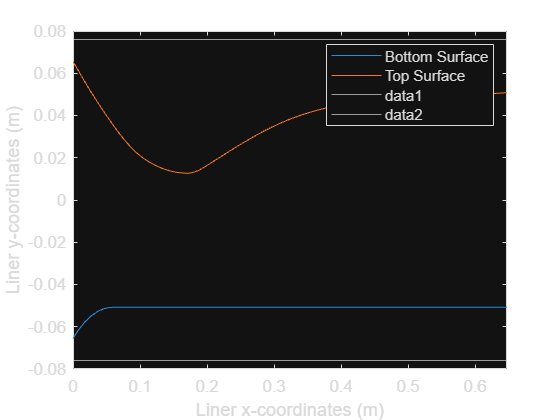


plot(bottomSurface_relative(:,1),bottomSurface_relative(:,2))
hold on
plot(topSurface_relative(:,1),topSurface_relative(:,2))
legend("Bottom Surface", "Top Surface")
xlabel("Liner x-coordinates (m)")
ylabel("Liner y-coordinates (m)")
yline(3*inch2m)
yline(-3*inch2m)
xlim([0 max(topSurface_relative(:,1))])
hold off

## Plotting the variation of the Mach number

To accomplish this, the ratio of the local area to the area at the throat. This ratio shows how the mach number varies through the wind tunnel, as pressure, area and velocity(and by extension mach number) are all related. As pressure increases due to a decrease in area, the velocity of the free stream air must also decrease. With this in mind, we can assume that the velocity - and therefore mach number - is at its lowest when at the throat, and at its highest elsewhere. We can then use this assumption and set the throat as a refenrence point to see how much larger the mach number will be in sections of the wind tunnel with larger areas. In theory, the mach number should not be lower than one, as that would suggest that the throat does not have the smallest area.

throatRadius = ( min(topSurface_relative(:,2)) - max(bottomSurface_relative(:,2)) )/2;
throatArea = pi*throatRadius^2

throatArea = 0.0032


localRadius = ( topSurface_relative(:,2) - bottomSurface_relative(:,2) )./2;
localArea = pi*localRadius.^2

localArea =     0.0135
    0.0120
    0.0103
    0.0088
    0.0077
    0.0068
    0.0061
    0.0055
    0.0050
    0.0046


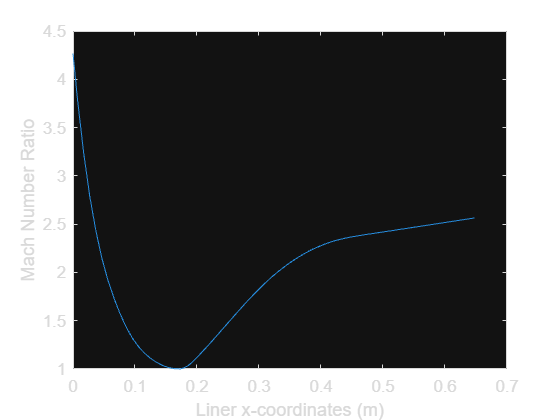


areaRatio = localArea/throatArea;

plot(topSurface_relative(:,1),areaRatio)
xlabel("Liner x-coordinates (m)")
ylabel("Mach Number Ratio")

# Task 1.2: WT measured pressure ratio and Mach number along working section at two  test conditions

The wind tunnel is run at 2 different pressures - 150psi and 75psi- these are the 2 conditions under which the working section is tested. 

### Preparing the raw data

The provided data has been given in text format and cannot easily be converted to a readable spreadsheet. To achieve a usable tabular format, the data will need to be split into individual elements and the reassembeled into a usable table/array. The following will be my attempt at accomplishing this using the knowledge from py4e.

% Loading the data into MATLAB
supersonic150_psi = readlines("WT Data for Further Aerodynamics cw\Supersonic Data\Data\supersonic150Psi.txt");
supersonic75_psi = readlines("WT Data for Further Aerodynamics cw\Supersonic Data\Data\supersonick75Psi.txt");
supersonicUncertaintity = readlines("WT Data for Further Aerodynamics cw\Supersonic Data\Data\Uncertainty.txt")

supersonicUncertaintity = 7×1 string array
    "Observation from experment"
    ""
    "Barometric pressure smallest unit: 10Pa"
    ""
    "VDAS Pressure Tapping smallest unit: 0.001 Bar"
    ""
    "[i.e. the above data are not the uncertainties but precision]"



%% Supersonic data at 150 psi

    % Creating an array to store the number of elements needed to iterate
    % through the data
    x = 1:numel(supersonic150_psi);
    
    % Defining the new array to be assembled
    supersonic150_PSI = zeros(1,28);
    
    % Removing empty cells
    for i = x
        line = supersonic150_psi(i);                    % store each cell as a separate line of text
        if line.startsWith("        data [Bar] ")       % check if the line starts with desired data
            line.strip("left");                         % remove undesired left spacing
            arr = strsplit(line);                       % split the strings
            arr(1) = [];                                % remove the empty cell on at start of line
            arr(1) = [];
            arr(1) = "Pressure [Bar]";
            str2double( arr(2:end) );
            supersonic150_PSI = vertcat(supersonic150_PSI,arr);             % concatenate with main array
        elseif line.startsWith("data [Bar]")
            arr = strsplit(line);
            arr(1) = [];
            arr(1) = "Pressure [Bar]";
            str2double( arr(2:end) );
            supersonic150_PSI = vertcat(supersonic150_PSI,arr);
        elseif line.startsWith("Pressure")                                  % generating the header names
            columnNames = strsplit(line,{':',' '},CollapseDelimiters=true);
            columnNames(1) = [];
            columnNames(1) = [];
            columnNames(1) = "Pressure Tap Number";
        end
    end
    
    supersonic150_PSI_tab = array2table(supersonic150_PSI);
    supersonic150_PSI_tab(1,:) = [];
    
    supersonic150_PSI_tab.Properties.VariableNames = columnNames;

%% Supersonic data at 75 psi


    % Creating an array to store the number of elements needed to iterate
    % through the data
    x = 1:numel(supersonic75_psi);
    
    % Defining the new array to be assembled
    supersonic75_PSI = zeros(1,28);
    
    % Removing empty cells
    for i = x
        line = supersonic75_psi(i);                    % store each cell as a separate line of text
        if line.startsWith("        data [Bar] ")       % check if the line starts with desired data
            line.strip("left");                         % remove undesired left spacing
            arr = strsplit(line);                       % split the strings
            arr(1) = [];                                % remove the empty cell on at start of line
            arr(1) = [];
            arr(1) = "Pressure [Bar]";
            str2double( arr(2:end) );             % converting the pressures from bar to Pa
            supersonic75_PSI = vertcat(supersonic75_PSI,arr);             % concatenate with main array
        elseif line.startsWith("data [Bar]")
            arr = strsplit(line);
            arr(1) = [];
            arr(1) = "Pressure [Bar]";
            str2double( arr(2:end) );
            supersonic75_PSI = vertcat(supersonic75_PSI,arr);
        elseif line.startsWith("Pressure")                                  % generating the header names
            columnNames = strsplit(line,{':',' '},CollapseDelimiters=true);
            columnNames(1) = [];
            columnNames(1) = [];
            columnNames(1) = "Pressure Tap Number";
        end
    end
    
    supersonic75_PSI_tab = array2table(supersonic75_PSI);
    supersonic75_PSI_tab(1,:) = [];
    
    supersonic75_PSI_tab.Properties.VariableNames = columnNames;

%% Converting from bar to Pa

    supersonic75_PSI_array = str2double( table2array( supersonic75_PSI_tab(:,2:end) ) );
    supersonic75_PSI_bar_array = supersonic75_PSI_array*bar2Pa + 269;

    supersonic150_PSI_array = str2double( table2array( supersonic150_PSI_tab(:,2:end) ) );
    supersonic150_PSI_bar_array = supersonic150_PSI_array*bar2Pa + 269;

    % Assembling tables of the converted values
    supersonic150_PSI_bar_tab = [supersonic150_PSI_tab(:,1)];
    supersonic150_PSI_bar_tab = horzcat( supersonic150_PSI_bar_tab,array2table(supersonic150_PSI_bar_array) );
    supersonic150_PSI_bar_tab.Properties.VariableNames = columnNames

supersonic150_PSI_bar_tab = 10×28 table
    Pressure Tap Number    [1]     [2]      [3]       [4]       [5]       [6]       [7]       [8]       [9]       [10]      [11]      [12]      [13]      [14]      [15]      [16]      [17]      [18]      [19]      [20]      [21]      [22]      [23]      [24]      [25]      [26]     →→
    ___________________    ___    _____    ______    ______    ______    ______


    supersonic75_PSI_bar_tab = [supersonic75_PSI_tab(:,1)];
    supersonic75_PSI_bar_tab = horzcat( supersonic75_PSI_bar_tab,array2table(supersonic75_PSI_bar_array) );
    supersonic75_PSI_bar_tab.Properties.VariableNames = columnNames

supersonic75_PSI_bar_tab = 10×28 table
    Pressure Tap Number    [1]     [2]      [3]       [4]       [5]       [6]       [7]       [8]       [9]       [10]      [11]      [12]      [13]      [14]      [15]      [16]      [17]      [18]      [19]      [20]      [21]      [22]      [23]      [24]      [25]      [26]     →→
    ___________________    ___    _____    ______    ______    ______    ______ 